clear

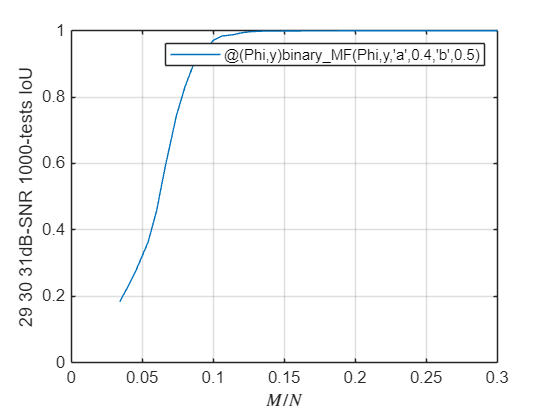

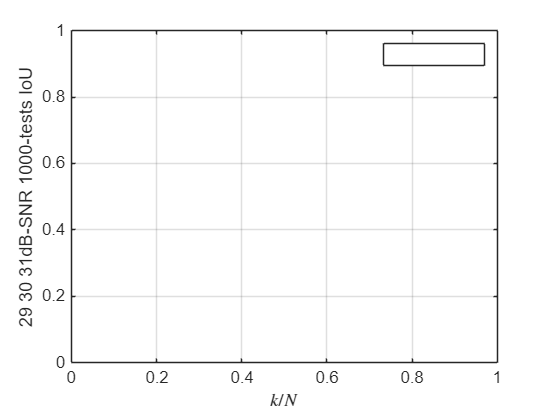

files = dir('data\');
files = files(~[files.isdir]);
[~,I] = sort({files.name});
files = files(I);

N = 500;
k = N * 0.05;
M = N * 0.5;
colName = "29 30 31dB-SNR 1000-tests IoU";

h1 = figure; hold on; xlabel('$M/N$', 'Interpreter','latex');
h2 = figure; hold on; xlabel('$k/N$', 'Interpreter','latex');

for i = 1:length(files)
    load(fullfile(files(i).folder, files(i).name))

    figure(h1); plotVaryingM(tbl, N, k, colName, algName)
    figure(h2); plotVaryingk(tbl, N, M, colName, algName)
end

for h = [h1 h2]
    figure(h)
    box on; grid on;
    ylabel(colName)
    legend('Interpreter','none')
    ylim([0 1])
    if contains(colName,"RED") || contains(colName,"RMD")
        ylim([1e-3 Inf])
        set(gca, 'YScale','log')
    end
end

function plotVaryingM(tbl, N, k, colName, algName)

tbl = convertvars(tbl, 1:3, "double");
mask = (tbl.N == N) & (tbl.k == k) & ~isnan(tbl.(colName));
M_over_N = tbl.M(mask) / N;
data = tbl.(colName)(mask);
[M_over_N, I] = sort(M_over_N);
data = data(I);
plot(M_over_N, data, 'DisplayName',algName)

end

function plotVaryingk(tbl, N, M, colName, algName)

tbl = convertvars(tbl, 1:3, "double");
mask = (tbl.N == N) & (tbl.M == M) & ~isnan(tbl.(colName));
k_over_N = tbl.k(mask) / N;
data = tbl.(colName)(mask);
[k_over_N, I] = sort(k_over_N);
data = data(I);
plot(k_over_N, data, 'DisplayName',algName)

end